# Projeto do dia 16/10/2020

João Guilherme Martins Jatobá

18.01790-8

ECM303 - Sistemas de Controle

**Boas práticas**

clear all;
clc;
close all;



**Definindo o sistema dinâmico**

N = 1;
D = [1 1]

D =      1     1



Gp = tf(N,D)

Gp =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



**Visualização**

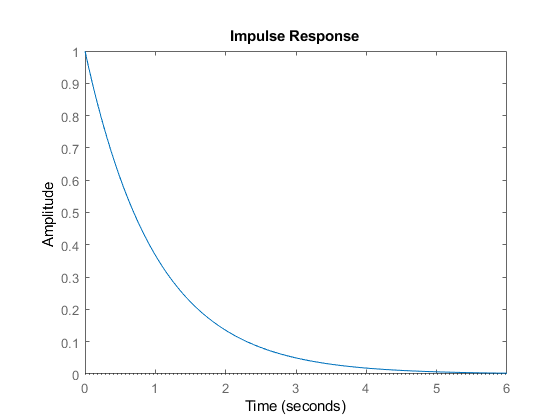

figure()
impulse(Gp)

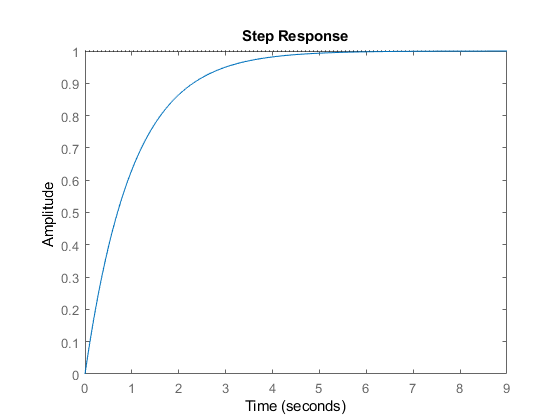


figure()
step(Gp)

**Sistema em Z**

T = 0.1;            %Taxa de amostragem
Nd = 1 - exp(-T);   %Numerador digital
Dd = [1 -exp(-T)];   % Denominador digital

Gpz = tf(Nd, Dd, T)     %funcao de transf discreta

Gpz =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



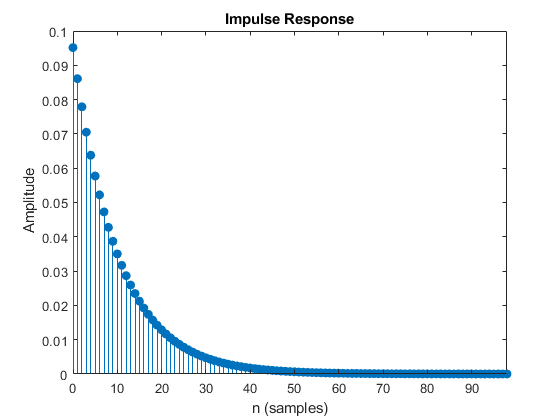


impz(Nd,Dd)

% impz(Gpz)

Error using signal.internal.sigcheckfloattype (line 67)
Input B in impz must be double/single, instead it was tf.

Error in impz (line 122)
  signal.internal.sigcheckfloattype(b,'','impz','B');

**Equação de Diferenças**


$$\frac{Y(z)}{U(z)} = \frac{a}{z-b} = \frac{az^{-1}}{1-bz^{-1}}$$


$y(n)  =au(n-1) + by(n-1)$(sera transformada em software)

**Trabalho**

% u(t) - acelerometro - entrada do sistema
% filtros passa baixas discreto de primeira ordem

%%% Gfiltros(s) = wc/(s+wc)

% Estimar wc

% Sugestao - FFT(u(T)) - descobrir a freq maxima de u(t) --> wc > fmax

% wc --> Gfiltro(s)
% Sugestao: usar o lsim para estimar o comportamento do filtro
%         : usar o comendo Bode para entender o filtro

% T - taxa de amostragem -- T = XXX.XXX segundos __> usar o diff para
% estimar a taxa de amsostragem
% Determinar Gfiltro(z)

% Determino a equacao de diferencas


**Solução**

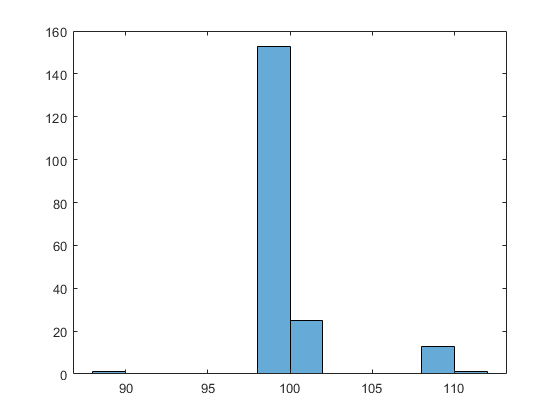

% Le os dados e atribui a variavel aux
aux = jsondecode(fileread('accelerometer_data.json'));


% vertcat transforma os dados em vetores
% Variavel tempo
tempo = vertcat(aux.timestamp);
figure()
histogram(diff(tempo))

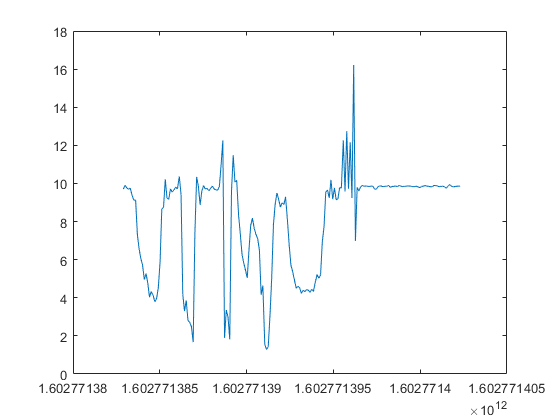



% Empilha os dados para ter vetor
plot(tempo,vertcat(aux.z));


% Taxa de amostragem ja em segundos
T = mean(diff(tempo))/1000;

**Análise espectral**

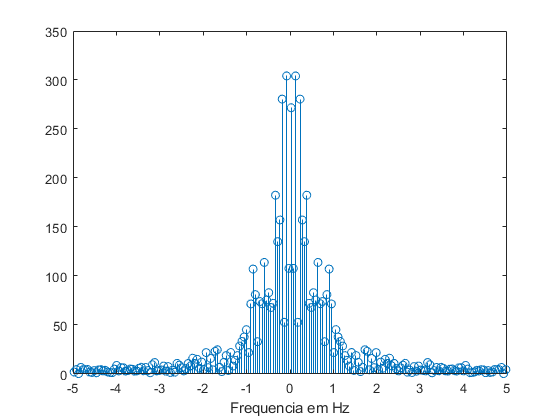

% Vetor com variavel x
Ac_x = vertcat(aux.x);

% Transformada rapida de Fourier da variavel x
Ac_x_W = fftshift(fft(Ac_x));

fs = 1/T; %freq de amostragem

M = length(Ac_x);   % numero de pontos

freq = linspace(-fs/2,fs/2,M); % frequencia do espectro
stem(freq,abs(Ac_x_W))
xlabel('Frequencia em Hz')

**Potência x Banda**

Pot_total = sum(abs(Ac_x_W).^2)

Pot_total = 7.6157e+05


Espectro_Unilateral = Ac_x_W(M/2+1:end)

Espectro_Unilateral = 	1.0e+02 *

  -2.7171 + 0.0000i
   0.9429 - 0.5220i
  -2.7395 + 1.3219i
   0.0031 + 0.5275i
  -0.1477 + 2.8013i
   1.5622 - 0.1722i
   0.9743 + 0.9355i
   0.7478 - 1.6641i
  -0.6981 + 0.1803i
   0.4815 + 0.4787i


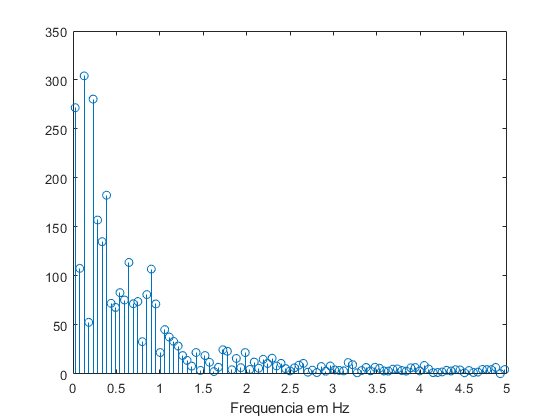


figure()
stem(freq(M/2+1:end),abs(Espectro_Unilateral))
xlabel('Frequencia em Hz')

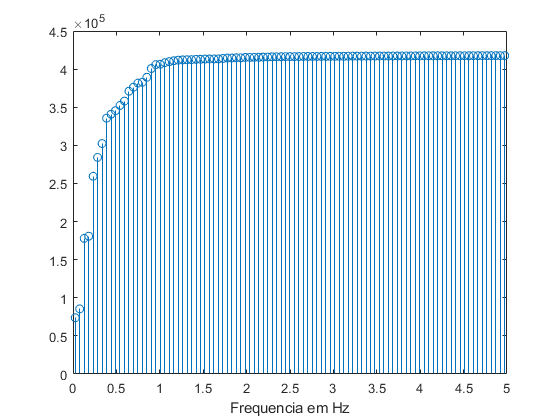


figure()
stem(freq(M/2+1:end),cumsum(abs(Espectro_Unilateral).^2))
xlabel('Frequencia em Hz')

**Conclusão**

N = 2*pi*2;    % freq de corte de filtro
D = [1 N];
gfiltro = tf(N,D) %ganho do filtro

gfiltro =
 
    12.57
  ---------
  s + 12.57
 
Continuous-time transfer function.





tempo = linspace(0,M*T,M);
Ac_filtro = lsim(gfiltro, Ac_x, tempo);


figure()
plot(tempo,Ac_filtro)
hold()

Current plot held


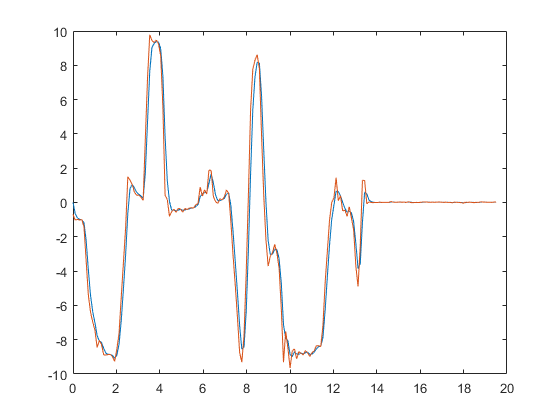

plot(tempo,Ac_x)

Filtro em z:


$$G_{filtro}(z) = 12.37\frac{z}{z-e^{-12.37*T}}$$


Para encontrar a Equação de Diferenças: 

$G_{ZOH} = 1-\frac{e^{-sT}}{s} $ e $G_{ZOH} = \frac{w_{corte}}{s+w_{corte}} = \frac{12.57}{s+12.57}$


$$G_{ma} =G_{ZOH}*G_{filtro} $$


Passando para domínio em Z:


$$G_{ma}(z) = (1-z^{-1})*Z\{ \frac{G_{filtro}}{s} \} =
(1-z^{-1})*Z\{ \frac{12.57}{s(s+12.57)} \}$$



$$\frac{12.57}{s(s+12.57)} = \frac{1}{s} - \frac{1}{s+12.57}$$



$$Z\{  \frac{1}{s} - \frac{1}{s+12.57}\} =Z\{  \frac{1}{s}\} - Z\{\frac{1}{s+12.57}\}$$


Fazendo a transforma em Z:


$$a-) Z\{  \frac{1}{s}\} = \frac{z}{z-1}$$



$$b-) Z\{\frac{1}{s+12.57}\} = \frac{z}{z-e^{-12.57*T}}$$



$$G_{ma}(z) = (1-z^{-1}) * (\frac{z}{z-1} - \frac{z}{z-e^{-12.57*T}}) = 1-(\frac{z-1}{z-e^{-12.57*T}}) = \frac{1-e^{-12.57*T}}{z-e^{-12.57*T}}$$



$$G_{ma}(z) = \frac{a}{z-b} = \frac{az^{-1}}{1-bz^{-1}}$$



$$\frac{Y(z)}{U(z)} = G_{ma}(z)$$



$$(1-bz^{-1})*Y(z) = az^{-1}*U(z)$$



$$Y(z)-Y(z)*bz^{-1} = az^{-1}*U(z)$$


Voltando pro tempo:


$$Y(K)-Y(K-1)b = aU(K-1)$$



$$Y(K) = aU(K-1) + Y(K-1)b = (1-e^{-12.57*T})U(K-1)+e^{-12.57*T}Y(K-1)$$



$$Y_M \left(K\right)=a\cdot U_M \left(K-1\right)+Y_M \left(K-1\right)\cdot b=\left(1-e^{-12,57\cdot T} \right)\cdot U_M \left(K-1\right)+e^{-12,57\cdot T} \cdot Y_M \left(K-1\right)$$
